# **Matlab案例代码解析**

## 1. 基础函数使用案例

### 1.2 文件读写

#### 1.2.5 读取视频每一帧并保存

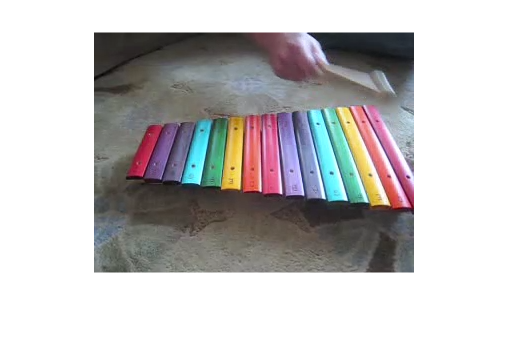

clear;clc;
% 读取视频数据
vidObj = VideoReader('xylophone.mp4');
% 帧数
frame_count = vidObj.NumFrames;
% 图像尺寸
row = vidObj.Height;
col = vidObj.Width;
% 保存所有图像数据，后期处理也是基于这个数据处理
video_data = struct('image_data', zeros(row, col, 3, 'uint8'));
% 依次读取每一帧
k = 1;
while hasFrame(vidObj)
    video_data(k).image_data = readFrame(vidObj);
    k = k + 1;
end
% 显示指定帧
indx = 100;
image_data = video_data(indx).image_data;
imshow(image_data);

% 保存图片
imwrite(image_data, 'data\video.bmp');